This script solves the MPC problem for a simple double integrator system.  Assuming a sampling time of 1 second, the system dynamics are given by 


$$x(k+1) = \pmatrix{1 & 1 \cr 0 & 1}x(k)+\pmatrix{0 \cr 1} u(k)$$



$$y(k) = \pmatrix{1 & 0}x(k)$$


 Let's use the objective function


$$J = \sum_{k=0}^1\left(y(k)^2+\frac{1}{10}u(k)^2\right)+x(2)^T\pmatrix{1 & 0 \cr 0 & 1}x(2)$$


and constrain the control inputs such that 


$$-1\leq u(k) \leq 1$$


Build the basic matrices for the problem.  If I were going to do anything more than this simple problem I would certainly loop the generation of the "barred" matrices.

A = [1 1;0 1];
B = [0;1];
R = 1/10;
Q = [1 0;0 0];  %Using knowledge of C
P = eye(2);
Qbar = blkdiag(Q,P);
Rbar = blkdiag(R,R);
Sbar = [B zeros(2,1);A*B B];
Tbar = [A;A^2];

Now convert into the form used by QP.

H = 2*(Rbar+Sbar'*Qbar*Sbar)

H =     4.2000    2.0000
    2.0000    2.2000


F = (2*Tbar'*Qbar*Sbar)'

F =      2     6
     0     2


G = [eye(2);-eye(2)]

G =      1     0
     0     1
    -1     0
     0    -1


W = [1;1;1;1]

W =      1
     1
     1
     1


S = zeros(4,2)

S =      0     0
     0     0
     0     0
     0     0


The pre-computation is done.  Now let's look at an online solution using Matlab's **quadprog** command to solve the optimization problem.

Setup the initial condition and run the approach for N steps (in this case, N seconds).  For sanity's sake, I'll also turn off the reporting that quadprog typically does.

X = [0 ;-1];
N = 40;
options = optimoptions('quadprog');
options.Display = 'none';
for ii = 1:N-1

The variable H is exactly what quadprog wants, but we have to modify the "f" argument to include the effects of the initial state.

    Xact(ii,:) = X; %For graphing
    f = F*X;

Solve the QP.

    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);  %Here is the magic!
    Uopt(ii) = Z(1);  %Just use the first item    

Now I'll apply the optimal control to the system.

    X = A*X+B*Z(1);
end
Xact(ii+1,:) = X;

Now let's see how well that worked.  It turns out that even with the tiny horizon (only 2 decision variables), it still worked OK.  We will soon talk about the relationship between prediction horizon and performance.

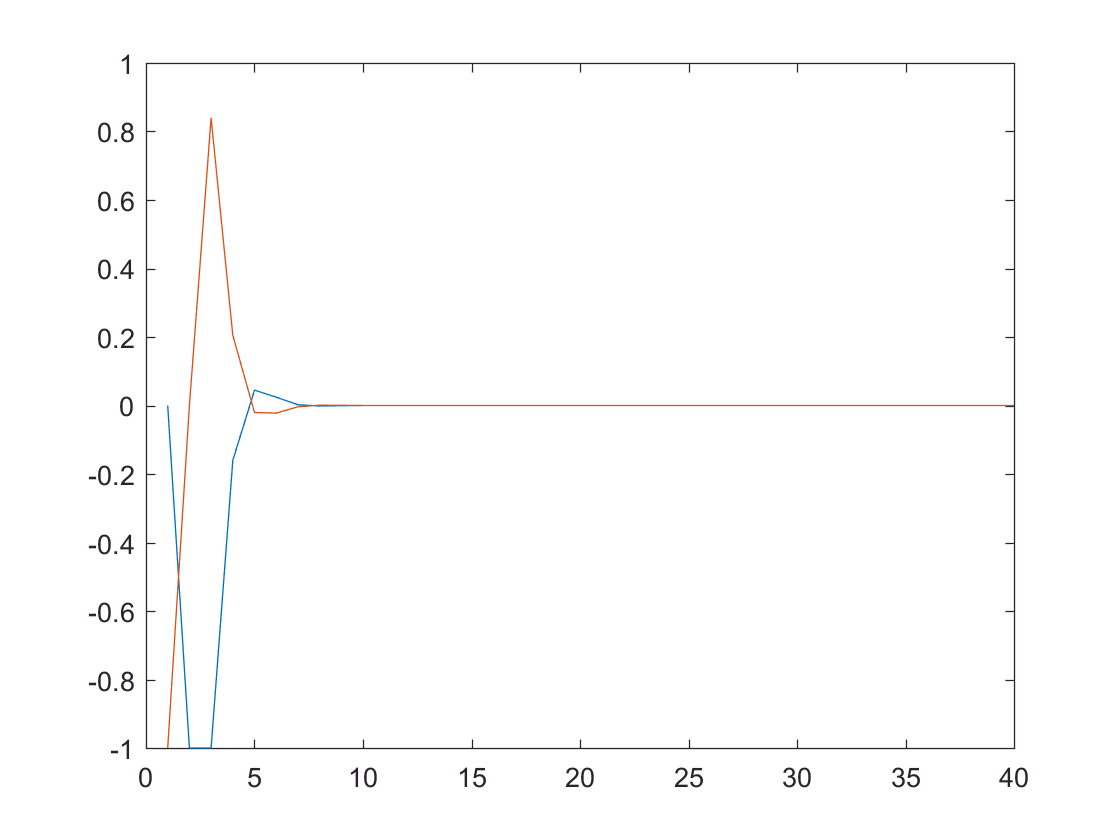

plot([1:N],Xact(:,1:2))

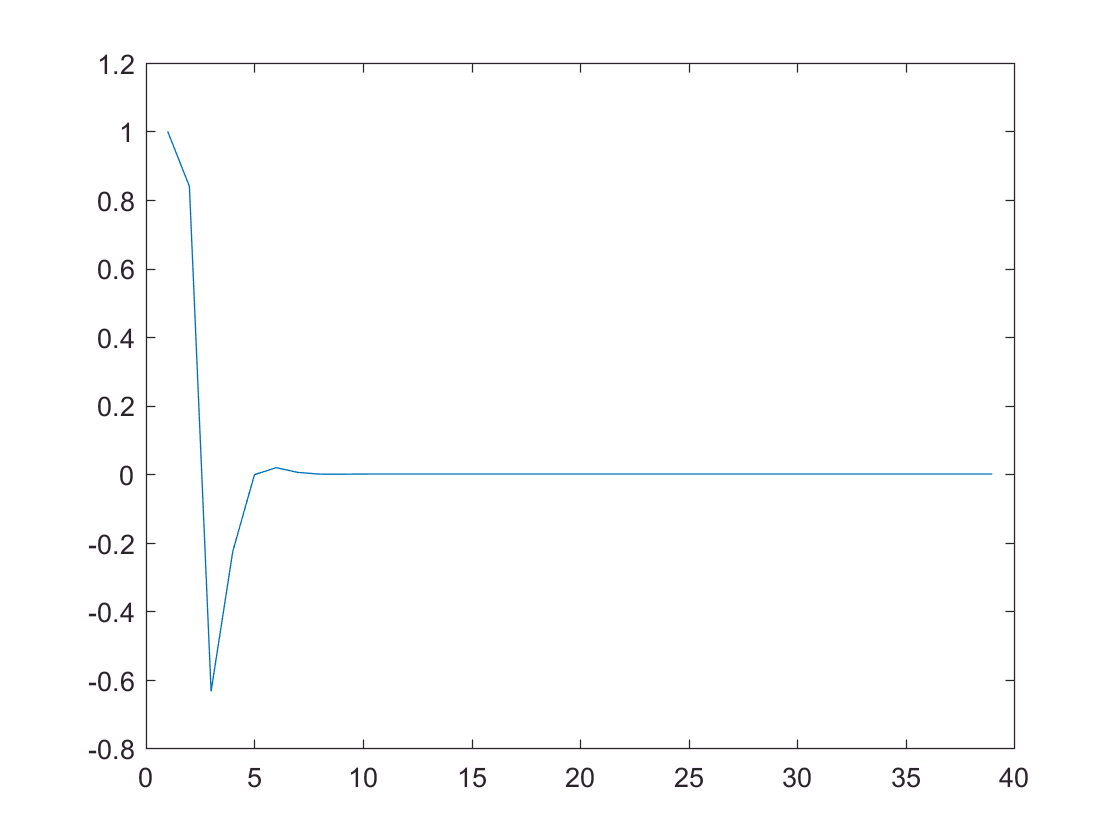

plot(Uopt)